# Initialize parameters

readdir = 'G:\My Drive\AlongTrack\';
writedir = 'G:\My Drive\AlongTrack\MyCode\';
JasonAlongTrack.filename = [readdir, 'JasonAlongTrack.nc'];
lat = ncread(JasonAlongTrack.filename, 'lat');
lon = ncread(JasonAlongTrack.filename, 'lon');
atd = ncread(JasonAlongTrack.filename, 'atd');
tn_0 = 84; %track number
lato = 24;
[~, lato_i] = min(abs(lat(:, tn_0)-lato));
lono = lon(lato_i, tn_0);
time = ncread(JasonAlongTrack.filename, 'time');

## Extract only the model region from the track matrix

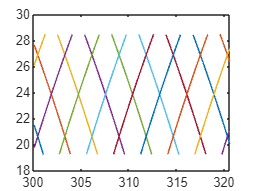

filename = 'BetaEddyOne.nc';
x = ncread([readdir, filename], 'x') / 1000; %km
y = ncread([readdir, filename], 'y') / 1000;
ssh = permute(squeeze(ncread([readdir, filename], 'ssh'))*100, [2, 1, 3]);
totalDays = size(ssh, 3);
%redefine x and y to be centered on the domain midpoint
xc = x - mean(x);
yc = y - mean(y);

%extract a subset of tracks

%first, grid x and y
[xg, yg] = ndgrid(xc, yc);

%covert these to longitude and latitude using a tangent plane
[latg, long] = xy2latlon(xg, yg, lato, lono); %spehrical geometry
%small angle approx
% [long,latg] = xy2lonlat(x,y, mean(x), mean(y), lono, lato);
%cylindrical coordinate with axis on the equator
% [latg,long] = TransverseMercatorToLatitudeLongitude(xg,yg,lon0=lono);
% % Normalize longitude to [-180, 180] range
% long = mod(long + 180, 360) - 180;
% latg = mod(latg + 180, 360) - 180;

%create a region enclosing minima and maxima lon and lat
region = [min(long(:)), max(long(:)), min(latg(:)), max(latg(:))];

%extract latitude and longitude for this region; t is for track
[latt, lont, timet] = trackextract(lat, lon, time, region);
lont = deg180(lont-lono) + lono; %avoids unwrapping issues

figure, plot(lont, latt)

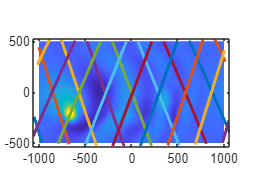


%finally, convert these latitudes and longitudes back to x and y
[xt, yt] = latlon2xy(latt, lont, lato, lono);

figure, jpcolor(xc, yc, ssh(:, :, end)), hold on
plot(xt, yt, linewidth = 2), axis tight, latratio(lato)

## Eddy-centered x,y track matrix

xo = 0.5 * (y(144) + y(145)); %origin defined based on eddy center
yo = 0.5 * (y(80) + y(81));
load('G:\My Drive\AlongTrack\MyCode\center_SSHMax.mat', 'center_xy')

%% sshmax center
% [center_xy, ~, ~]=findSSHMaxContour(x,y,ssh);
%% zeta-zero contour centroid
% [center_xy, core_xy, coreE_xy]=findCenterZeroZeta(x,y,zeta2D,ssh2D);

% center_xy changed back to lonlat to ensure xy is center is subtracted
% without [-180,180] conversion, but improve this later
% [center_lonlat(:, 2),center_lonlat(:, 1)]=xy2latlon(center_xy(:, 1)-xo,center_xy(:, 2)-yo,lato,lono); %spehrical geometry
% center_lonlat(:, 1) = deg180(center_lonlat(:, 1)-lono) + lono; %avoids unwrapping issues
% % %find eddy center on model lon,lat matrix
% for n = 1:totalDays
%     lonEt(:, :, n) = lont - (center_lonlat(n, 1) - center_lonlat(1, 1));
%     latEt(:, :, n) = latt - (center_lonlat(n, 2) - center_lonlat(1, 2));
%     [xEt(:, :, n), yEt(:, :, n)] = lonlat2xy(lonEt(:, :, n), latEt(:, :, n), xo, yo, lono, lato);
%     % [xEt(:, :, n), yEt(:, :, n)] = latlon2xy(latEt(:, :, n), lonEt(:, :, n), lono, lato);
% end
% xEt = xEt - (center_xy(1, 1));
% yEt = yEt - (center_xy(1, 2));
for n = 1:totalDays
xEt(:,:,n)=xt-(center_xy(n,1)-mean(x));
yEt(:,:,n)=yt-(center_xy(n,2)-mean(y));
end

## Interpolate ssht per day from the model ssh

%convert x,y from model to lat lon
[xMat,yMat]=meshgrid(xc,yc);
%find time array within the repeating cycle
timesortMat = [];
sortindMat = [];
%track where there's min nan
nan_counts = sum(isnan(timet(:, :, 1)), 1);
[~, minNanCol] = min(nan_counts);
for n = 1:totalDays
    [timesort, sortind] = sort(timet(minNanCol, :, n), 2);
    timesortMat = [timesortMat; timesort];
    sortindMat = [sortindMat; sortind];
end
trackday = floor(timesortMat-min(timesortMat(:))) + 1;
ssht = NaN([size(yt), totalDays]);
for n = 1:totalDays
    [row, col] = find(trackday == n);
    if isempty(row)
        continue
    end
    rr = unique(row);
    colkeep = sortindMat(rr(1), col);
    if size(rr) > 1
        colkeep = [colkeep, sortindMat(rr(2), col)];
    end
    xtii = NaN(size(xt));
    xtii(:, colkeep) = xt(:, colkeep);
    ytii = NaN(size(yt));
    ytii(:, colkeep) = yt(:, colkeep);
    ssht(:, :, n) = interp2(xMat, yMat, ssh(:, :, n), xtii, ytii, 'linear', 0);
end

## Define bin

dbindeg = 10; %degree
dbin = round(dbindeg/(x(2) - x(1))); %index
dbinX = dbin * (x(2) - x(1)); %km
xEbound = min(abs([min(xEt(:)), max(xEt(:)), 250]));
rbin = [fliplr([0:-dbinX:-xEbound]), dbinX:dbinX:xEbound];
xEbin = rbin;
yEbin = xEbin;

## Assign ssht to bins

sshBin = zeros(length(xEbin), length(yEbin), totalDays);
count_binAll = zeros(length(xEbin), length(yEbin), totalDays);
sum_bin = zeros(length(xEbin), length(yEbin));
count_bin = zeros(length(xEbin), length(yEbin));
for nn = 1:totalDays
    for i = 1:length(xEbin) - 1
        for j = 1:length(yEbin) - 1
            % Track elements that falls in the bin ranges
            [row, col] = find(xEt(:, :, nn) >= xEbin(i) & xEt(:, :, nn) <= xEbin(i+1) & yEt(:, :, nn) >= yEbin(j) & yEt(:, :, nn) <= yEbin(j+1));
            % if ~isempty(row) || ~isempty(col)
            %      % No data in this bin, continue to the next bin
            %      keyboard;
            %  end
            bin_data = ssht(row, col, nn); % this is where I need to edit that each snapshot takes different xEt,yEt location.
            sum_bin(j, i) = sum(bin_data, 'all', 'omitmissing');
            count_bin(j, i) = sum(~isnan(bin_data), 'all');
        end
    end
    sshBin(:, :, nn) = sum_bin ./ count_bin .* (count_bin ~= 0);
    count_binAll(:, :, nn) = count_bin;
end

## Azimuthal profile

AvgsshAccum = zeros(size(xEt));
AvgsshAccumBin = zeros(length(yEbin), length(xEbin), totalDays);
sshAccumBin = sshBin;
% Output how many counts there are to see if it's enough sample numbers
% and suggest alternative bin space.
AvgsshAccumBin = mean(sshAccumBin, 3, 'omitnan');
[~, AvgAzi, stdAziAvgTemp, stdTemp2D, AvgAziStdTemp, stdTotal, bins, err] = AvgProf(xEbin, yEbin, sshAccumBin);

%% Using twodstat
sshtValid=ssht(:);validInd=~isnan(sshtValid);sshtValid=sshtValid(validInd);
xEtValid=xEt(:);xEtValid=xEtValid(validInd);
yEtValid=yEt(:);yEtValid=yEtValid(validInd);
[mz2,xmid2,ymid2,numz2,stdz2]=twodstats(xEtValid, yEtValid,sshtValid, xEbin, yEbin);

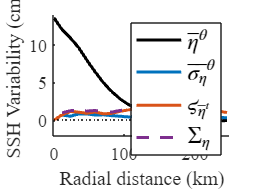

%plot profile
prettyblue = [0, 0.4470, 0.7410];
prettyorange = [0.8500, 0.3250, 0.0980];
prettyyellow = [0.9290, 0.6940, 0.1250];
prettypurple = [0.4940, 0.1840, 0.5560];
prettygreen = [0.4660, 0.6740, 0.1880];
figure; hold on
h1 = plot(bins, AvgAzi, 'LineWidth', 2, 'Color', 'k');
h2 = plot(bins, AvgAziStdTemp, 'LineWidth', 2, 'Color', prettyblue);
h3 = plot(bins, stdAziAvgTemp, 'LineWidth', 2, 'Color', prettyorange);
h4 = plot(bins, stdTotal, 'LineWidth', 2, 'Color', prettypurple, 'linestyle', '--');
xlabel('Radial distance (km)', 'FontName', 'times')
ylabel('SSH Variability (cm)', 'FontName', 'times')
set(gca, 'fontname', 'times')
% xlim([0,250]);ylim([-2,14])
% zero horizontal line
plot([bins(1), bins(end-1)], [0, 0], 'k:')
% lg=legend([h1 h2 h3 h4],'$\overline{\psi}^\theta$','$\varsigma_{\overline{\psi}^t}$','$\overline{\sigma_\psi}^\theta$','$\Sigma_{\psi}$');
lg = legend([h1, h2, h3, h4], '$\overline{\eta}^\theta$', '$\overline{\sigma_\eta}^\theta$','$\varsigma_{\overline{\eta}^t}$', '$\Sigma_{\eta}$');
set(lg, 'interpreter', 'latex', 'fontsize', 15, 'orientation', 'vertical')
set(gca, 'fontsize', 12)
xlim([0, 250]); ylim([-2, 14])

set(gcf, 'color', 'white')

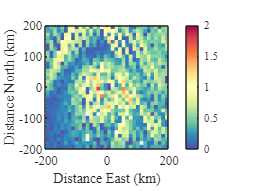

% Composite contour
figure;
jpcolor(xmid2, ymid2, stdz2);
% jpcolor(xEbin, yEbin, stdTemp2D);
shading flat
% hold on
% contour(xE,yE,stdTemp2D,[0:0.1:2],'k')
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
colorbar('EastOutside');
xlim([-200, 200]), ylim([-200, 200]); clim([0, 2])

set(gcf, 'color', 'white')

% mean ssh 2D
figure;
jpcolor(xmid2, ymid2, mz2)
% jpcolor(xEbin, yEbin, AvgsshAccumBin)
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
colorbar('EastOutside');
xlim([-200, 200]), ylim([-200, 200]);
clim([-2.5, 12])
set(gcf, 'color', 'white')

% 2D track counts histogram
figure;
[hist, xmidHist, ymidHist] = twodhist(xEt(:), yEt(:), xEbin, yEbin);
jpcolor(xmidHist, ymidHist, hist)%log10(mat)
clim(round([min(hist(:)), max(hist(:))]))
% % orginal counts
% countAll_lastday = sum(count_binAll, 3);
% countAccumBin = sum(count_binAll, 3);
% countAccumBin(countAccumBin == 0) = nan;
% jpcolor(xEbin, yEbin, countAccumBin)
% clim(round([min(countAll_lastday(:)), max(countAll_lastday(:))]))
shading flat
axis equal
xlabel('Distance East (km)', 'FontName', 'times')
ylabel('Distance North (km)', 'FontName', 'times')
set(gca, 'fontname', 'times')
colormap(brewermap([], '-Spectral'))
colorbar('EastOutside');
xlim([-200, 200]), ylim([-200, 200]);
set(gcf, 'color', 'white')

## Jonathan's code: radialStatisticsFromScattered

clearvars stdAziAvgTemp AvgAziStdTemp stdTempAvgAzi AvgTempStdAzi t
for n = 1:totalDays
    t(:, :, n) = ones(size(xEt, 1), size(xEt, 2)) * n;
end
tbin = [1:totalDays];
dbindeg = 10; %degree
dbin = round(dbindeg/(x(2) - x(1))); %index
dbinX = dbin * (x(2) - x(1)); %km
xEbound = min(abs([min(xEt(:)), max(xEt(:)), 250]));
rbin = [fliplr([0:-dbinX:-xEbound]), dbinX:dbinX:xEbound];
% Compute statistics
[mz, rmid, numz, stdAziAvgTemp, AvgAziStdTemp] = radialStatisticsFromScattered(xEt, yEt, t, ssht, rbin, tbin, firstAverage = 'temporal');
[mz, rmid, numz, stdTempAvgAzi, AvgTempStdAzi] = radialStatisticsFromScattered(xEt, yEt, t, ssht, rbin, tbin, firstAverage = 'azimuthal');
% Std Total
stdTotal1 = sqrt(stdAziAvgTemp.^2+AvgAziStdTemp.^2);
stdTotal2 = sqrt(stdTempAvgAzi.^2+AvgTempStdAzi.^2);

%plot

figure; hold on
h1 = plot(rmid, mz, 'LineWidth', 2, 'Color', 'k', 'linestyle', '-');
h2 = plot(rmid, AvgAziStdTemp, 'LineWidth', 2, 'Color', prettyblue, 'linestyle', '-');
h3 = plot(rmid, stdAziAvgTemp, 'LineWidth', 2, 'Color', prettyorange, 'linestyle', '--');
h4 = plot(rmid, AvgTempStdAzi, 'LineWidth', 2, 'Color', prettyyellow, 'linestyle', ':');
h5 = plot(rmid, stdTempAvgAzi, 'LineWidth', 2, 'Color', prettygreen, 'linestyle', '-.');
h6 = plot(rmid, stdTotal1, 'LineWidth', 2, 'Color', prettypurple, 'linestyle', '--');
h7 = plot(rmid, stdTotal2, 'LineWidth', 2, 'Color', prettypurple, 'linestyle', '-');

xlabel('Radial distance', 'FontName', 'times')
ylabel('SSH Variability', 'FontName', 'times')
set(gca, 'fontname', 'times')
% % zero horizontal line
plot([rmid(1), rmid(end-1)], [0, 0], 'k:')
lg = legend([h1, h2, h3, h4, h5, h6, h7], '$\overline{\mathrm{z}}^\theta$', '$\overline{\sigma_\mathrm{z}}^\theta$', '$\varsigma_{\overline{\mathrm{z}}^t}$', '$\overline{\varsigma_\mathrm{z}}^t$', '$\sigma_{\overline{\mathrm{z}}^\theta}$', '$\Sigma_{z}$', '$\Sigma_{z,2}$');
set(lg, 'interpreter', 'latex', 'fontsize', 15, 'orientation', 'vertical','NumColumns',2)
set(gca, 'fontsize', 12)
xlim([0, 250]); ylim([-2, 14])